
$$\begin{array}{l}
\text{ECSE}\text{ }307-\text{Winter}\text{ }2018\text{                                                                                                        }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{           }\text{ }\text{Professor}\text{ }\text{Aditya}\text{ }\text{Mahajan}\\
\text{                                                                                                                         }\text{ }\text{ }\text{ }\text{                       }\text{ }\text{TA}:\text{Mohammad}\text{ }\text{Afshari}\text{ }\text{and}\text{ }\text{Anas}\text{ }\text{El}\text{ }\text{Fathi}
\end{array}$$


# 
$$\text{Lab}\text{ }7$$


# 
$$\mathrm{Frequency}\text{ }\mathrm{Domain}\text{ }\mathrm{Identification}\text{ }\mathrm{of}\text{ }\mathrm{Qnet}\text{ }\mathrm{DC}\text{ }\mathrm{Motor}$$


%* Fill in your group number----------------------------------------------%
GroupeNum = 19;
%* Fill in your student Name and ID--------------------------------------*%
Students(1).Name = 'Yassine Douida';
Students(1).ID   = '260741964';
Students(2).Name = 'Nayem Alam';
Students(2).ID   = '260743549';
%-------------------------------------------------------------------------%

## **0. Objectives**

In this lab, we will use frequency analysis to identify the transfer function of QNET Allied Motion CL40 Series Coreless DC Motor (model 16705).

The lab uses `MATLAB` to interface with the DC Motor. To verify that the hardware is working, run the following (You can ignore the warnings, but you shouldn't have any errors)

Motor = QnetDCMotor();

## **1. Instructions**

Follow carefully step 1, 2 and 4 in the guide `QNET DC Motor Quick Start Guide.pdf` to make sure your Qnet DC Motor is setup correctly.

You should put the file `QnetDCMotor.m` in the same folder as this livescript.

All files are available in myCourses [Labs](https://mycourses2.mcgill.ca/d2l/le/content/305096/Home).

At the end of the lab, please make a group submission of:

- This LiveScript once completed.

- The PDF report generated from the LiveScript.

## **2. Frequency Response Analysis**

When a cosine wave $x(t) = M_x \cos(\omega t)$ is injected into a linear system, the system will respond with the same frequency $\omega$, a certain magnitude $M_x$ and a certain phase angle relative to the input $\phi$. The steady-state system output can be written as $y(t) = M_y \cos(\omega t + \phi)$.

If $G(j \omega)$ is the frequency response of this system, we define the magnitude and phase at $\omega$ by:


$$M(\omega) = \frac{M_y}{M_x} = || G(j \omega) ||$$



$$\phi(\omega) = \angle G(j \omega)$$


## *1.1 Bode plot*

The Bode plot presents the magnitude and the phase shift between the input and output at each frequency. It is possible to draw a “point-by-point” Bode plot by injecting a cosine wave with a fixed frequency and measuring the magnitude and phase shift of the output after it reaches its steady-state.

In a bode plot the magnitude is represented in a logarithmic scale in decibels (db).


$$M_{db}(\omega) = 20 \log(M_(\omega))$$


The phase at each frequency can be found by measuring the temporal delay between the output and the input when the input is a cosine wave. Another way to measure the phase shift is through the Lissajous method. A Lissajous curve (an ellipsoide) is found when we try to plot the output in function of the input (XY plot). In fact, we can show that at a frequency $\omega$


$$\cos(\phi) = \frac{y^*}{M_y}$$


Where $y^*$ is the value of the output $y$ when the input $x$ is at the maximum $M_x$.

An illustration of using the Lissajous method (taken from Wikipedia) is shown below:

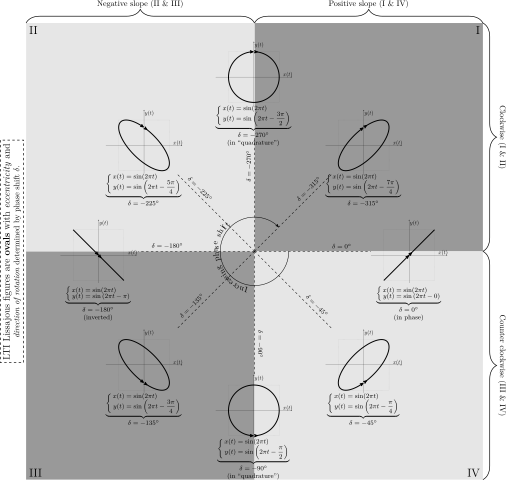

## *Question 1 (2.5 mark)*

- Define the following transfer function in `MATLAB` 


$$G(s) = \frac{s + 4}{s^2+s+1}$$


syms s;
G = tf([1 4],[1 1 1])


G =
 
     s + 4
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



- Plot the bode graph of this system. (Hint: help `bode`)

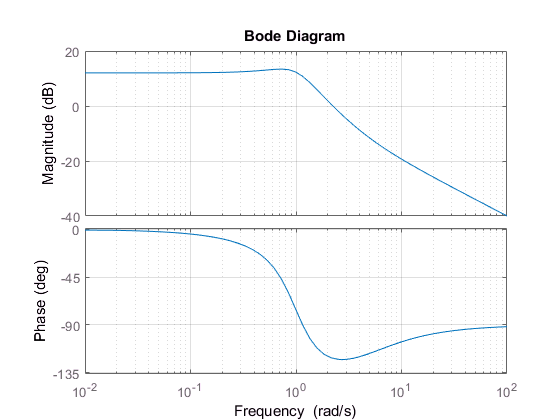

figure(1); clf;
bode(G)
grid on

- Consider the following signal:

rng(datetime('now').Year*GroupeNum)
Freq = round(0.1 + rand(1), 2);
time = 0:0.01:round(10/Freq);
x = cos(2*pi*Freq*time);

Using `lsim` simulate the output $y(t)$ representing the response of the system $G$ to the signal $x(t)$.

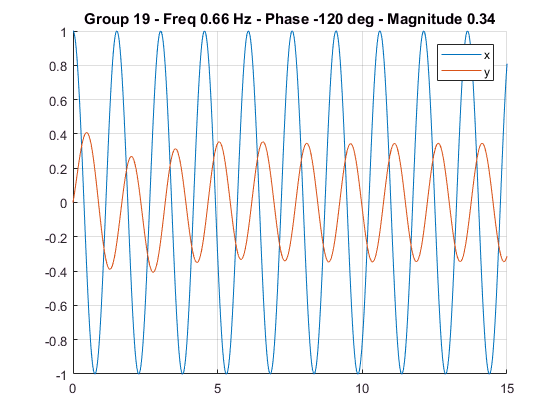


y = lsim(G,x,time);

figure(2); clf;
title(sprintf('Group %d - Freq %3.2f Hz - Phase %+03d deg - Magnitude %4.2f', GroupeNum, Freq, round(180*angle(evalfr(G, 2*pi*Freq*1i))/pi), abs(evalfr(G, 2*pi*Freq*1i))));
hold on
plot(time, x)
plot(time, y)
grid on
legend('x', 'y')

- Plot $y(t)$ in function of $x(t)$. 

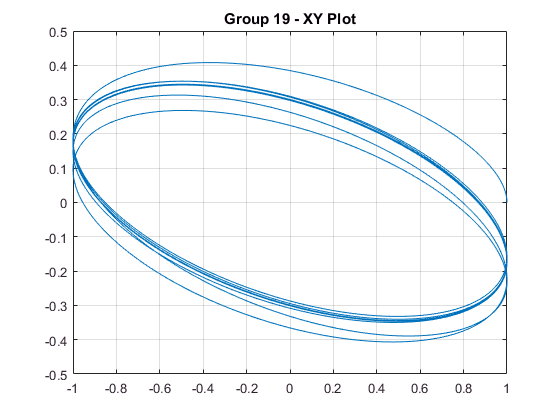

figure(3); clf;
plot(x,y)
title(sprintf('Group %d - XY Plot', GroupeNum));
grid on

- Find graphically the phase $\phi$ and magnitude $M$ at the specified frequency.

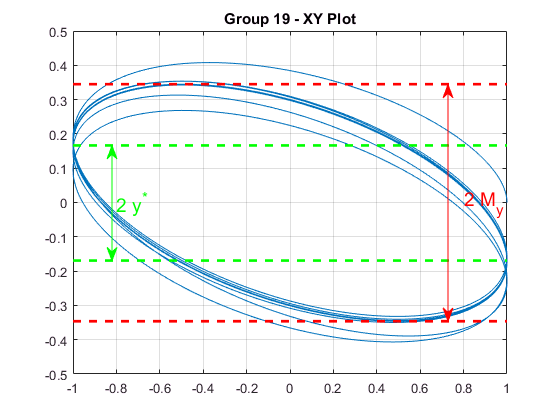

% This code shows you M_y and y*
max_y = max(y(time > round(5/Freq)));
max_x = max(x(time > round(5/Freq)));
min_y = min(y(time > round(5/Freq)));
min_x = min(x(time > round(5/Freq)));
star_y_1 = mean(y(time > round(5/Freq) & abs(x - max_x) < 0.05));
star_y_2 = mean(y(time > round(5/Freq) & abs(x - min_x) < 0.05));
figure(3); hold on; axPos = get(gca,'Position'); xMinMax = xlim; yMinMax = ylim;
plot([min_x, max_x], [max_y, max_y], '--r', 'linewidth', 2.0)
plot([min_x, max_x], [min_y, min_y], '--r', 'linewidth', 2.0)
annotation('doublearrow', [0.8 0.8], axPos(2) + (([max_y min_y]- yMinMax(1))/(yMinMax(2)-yMinMax(1))) * axPos(4), 'Color','red')
text(0.8, 0.0, '2 M_y', 'Color','red', 'FontSize',14)
plot([min_x, max_x], [star_y_1 star_y_1], '--g', 'linewidth', 2.0)
plot([min_x, max_x], [star_y_2 star_y_2], '--g', 'linewidth', 2.0)
annotation('doublearrow', [0.2 0.2], axPos(2) + (([star_y_1 star_y_2]- yMinMax(1))/(yMinMax(2)-yMinMax(1))) * axPos(4), 'Color','green')
text(-0.8, 0.0, '2 y^*', 'Color','green', 'FontSize',14)


% Write phase and magnitude here
y_star = (0.1664+0.1693)/2;
My = (0.3448+0.3463)/2;
Mx = 1;

phi = acos(y_star/My)

phi = 1.0636

M = 20*log10(My/Mx)

M = -9.2298

## **3. Identification of Qnet DC Motor Frequency Response**

To avoid the non-linear domain of the DC Motor at low voltage we will stimulate the DC Motor with offsetted cosine waves. We choose the following voltage signal:


$$v(t) = 4 + 2 \cos(2 \pi f t)$$


To send a cosine wave of frequency $f = 0.5$ Hz to the Qnet DC Motor we do the following

dt = 0.01; % sampling time
T = 15; % simulation duration
time = 0:dt:T; % define the time signal

vAmp = 2;    % cosine amplitude
vOffset = 4; % voltage offset

Freq = 0.5;  % frequency of cosine wave

Motor.reset;

for t = time
    % Generate a cosine wave input at current time
    v = vOffset + vAmp*cos(2*pi*Freq*t);
    
    % Drive motor for a duration of dt
    Motor.drive(v, t, dt);
end
Motor.off;

For frequency analysis we are only interseted at the steady-state response. We can retrieve the resulting angular velocity at steady state by:

delay = 5; % Ignore the first 5 seconds of experiment
t = Motor.time(delay, T);
w = Motor.velocity(delay, T);
v = Motor.voltage(delay, T);

The following shows a plot of the temporal response.

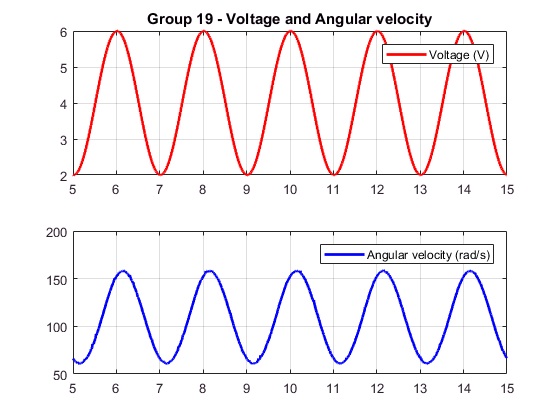

figure(4), clf;
subplot(2,1,1);
plot(t,v, 'r', 'linewidth', 2.0);
legend('Voltage (V)')
grid on
xlim([delay, T])
title(sprintf('Group %d - Voltage and Angular velocity', GroupeNum));
subplot(2,1,2);
plot(t,w, 'b', 'linewidth', 2.0);
legend('Angular velocity (rad/s)')
grid on
xlim([delay, T])

And the following shows the XY plot, and how to find $y^*$, $M_y$ and $M_x$.

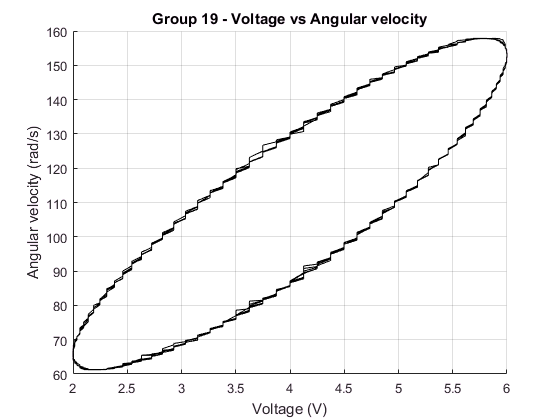

w_filter = medfilt1(w, 10, 'truncate'); % we can filter the noise

figure(5), clf; hold on;
title(sprintf('Group %d - Voltage vs Angular velocity', GroupeNum));
plot(v,w_filter, 'k');
grid on
xlabel('Voltage (V)')
ylabel('Angular velocity (rad/s)')

## *Question 3 (3.0 marks)*

Find the magnitude and phase of the transfer function of the Qnet DC Motor for the following frequencies.

FreqVect = [0.05, 0.1, 0.2, 0.4, 0.6, 0.8, 1.0, 1.2, 2.0, 4.0, 6.0];

% choose a frequency
Freq = 6.0;

% choose a duration 
T = 2/Freq + 5;
time  = 0:dt:T;     % A vector containing all time samples

% stimulate DC motor with the cosine wave
Motor.reset;

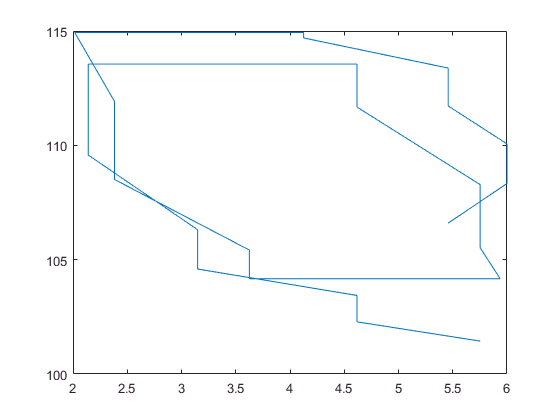

for t = time
    % Generate a cosine wave input at current time
    v = vOffset + vAmp*cos(2*pi*Freq*t);
    
    % Drive motor for a duration of dt
    Motor.drive(v, t, dt);
end
Motor.off;

% choose a delay
delay = 5;
t = Motor.time(delay, T);
w = Motor.velocity(delay, T);
w_filter = medfilt1(w, 10, 'truncate');
v = Motor.voltage(delay, T);

% XY Plot
figure(6); clf;
plot(v,w_filter)


% Measure graphically the phase and magnitude and put it here
%Magnitude for freq values from 0.05 to 6
MagnitudeDB = 20*log10([27.6, 28.9, 28.2, 27.9, 26.39, 25.6, 24.6 , 23.5 , 21.2 , 14.8, 8.35 ]);

PhaseDeg = [0 , 0 , -9.83, -20.71 , -34.7 , -45.2 , -52.44, -59.5, -80.9 , -105.4, -114.1];

## *Question 4 (1.0 mark)*

Draw the resulting Bode plot (Magnitude (dB) vs Frequency (Hz) on a semilog plot and Phase (deg) vs Frequency (Hz) on a semilog plot). (Hint: help `semilogx`)

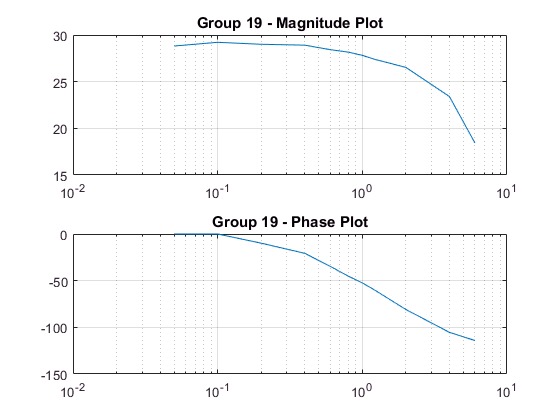

omega = 2*pi*FreqVect;
figure(7); clf;
subplot(2,1,1)
%[Draw magnitude here]

semilogx(FreqVect,MagnitudeDB)
title(sprintf('Group %d - Magnitude Plot', GroupeNum));



grid on
subplot(2,1,2)
%[Draw Phase here]

semilogx(FreqVect,PhaseDeg)
title(sprintf('Group %d - Phase Plot', GroupeNum));
grid on

## *Question 5 (1.0 mark)*

From the Bode plot, measure the DC gain.

DC_gain = 27.6; % we got this value from taking the first point of the magnitude plot.

## *Question 6 (1.0 mark)*

From the Bode plot, measure the cut-off frequency (Frequency at which the magnitude drops by a factor of $-20\log_{10}\left(\frac{1}{\sqrt{2}}\right)=-3$ (dB) from the DC gain).

w_cutoff = 2*pi*0.6; % we found the cutoff frequency from the graph.

## *Question 7 (1.5 mark)*

For a first order system the transfer function is expressed by 


$$H = \frac{DC_{gain}}{1 + \frac{s}{w_{cutoff}}}$$


- Write the transfer function of the identified DC Motor.

s = tf('s');

H = DC_gain/(1+(s/w_cutoff))


H =
 
    95.38
  ---------
  s + 3.456
 
Continuous-time transfer function.



- Complete the code to superpose the experimental bode plot with the bode plot of the identified transfer function.

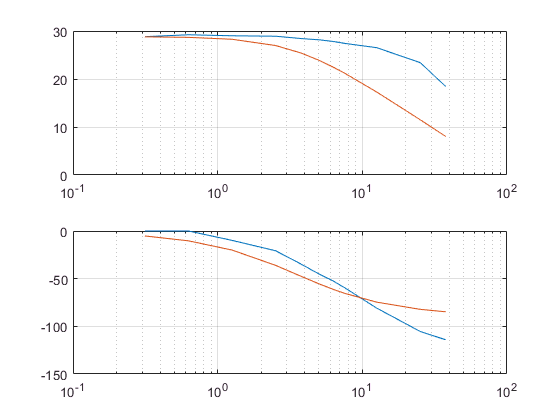

H_Freq = squeeze(freqresp(H, omega, 'rad/s'))';

H_MagnitudeDB = 20*log10(abs(H_Freq)); % find magnitude in db
H_PhaseDeg = -angle(H_Freq)*(180/pi); % find phase in degrees

figure(8)
subplot(211)
semilogx(omega, [MagnitudeDB; H_MagnitudeDB])
grid on
subplot(212)
semilogx(omega, [PhaseDeg; H_PhaseDeg])
grid on

- How accurate is the point-by-point bode plot for high frequencies ? Comment on your results.

% The point by point magnitude bode plot is somewhat accurate because of our DC gain and 
% cutoff frequency; with some discrepancy possibly due to artimetic error.
% Moreover, the phase plot seems relatively accurate with some inconsistency. 